# Homework 2: Hough Transform

#### Name: Grant Roberts

#### Date: 02/12/2020

#### Due: 02/25/2020

#### BMI/CS 567: Medical Image Analysis 

**In this homework you will implement the Hough transform and use it to find lines in a medical image.**

**(a) Create your own function to implement the Hough Transform.**

See `hough_transform and hough_transform_fast `in "Custom Functions" at the end of this document.

The first function (`hough_transform) `is the easiest implementation and is relatively easy to understand. However, it takes alomst 2-3x as long as the second function (`hough_transform_fast)`. The second function utilizes matrix multiplication to avoid a for loop, however, it is much less intuitive. I will be using the second function from here forward, but it may be easier to grade the first function.

**(b) Create an artificial image that only has three aligned points. Use **`subplot`** to display :**

img = zeros(256); % create 256x256 image of zeros
img(20,66) = 1; % fill in 3 points based on the line y=3x+6
img(50,156) = 1;
img(80,246) = 1;

- **(i) the original image        **

figure; subplot(1,3,1); imagesc(img); title('Original Image');

- **(ii) its Hough transform produced by your code**

% tic; my_hough = hough_transform(img); toc
tic; my_hough = hough_transform_fast(img); toc

Elapsed time is 0.006666 seconds.


subplot(1,3,2); imagesc(my_hough); title('My Hough Transform'); h = gca; h.Visible = 'On';

- **(iii) its Hough transform produced by Matlab's **`hough`** function. **

tic; matlab_hough = hough(img); toc

Elapsed time is 0.001796 seconds.


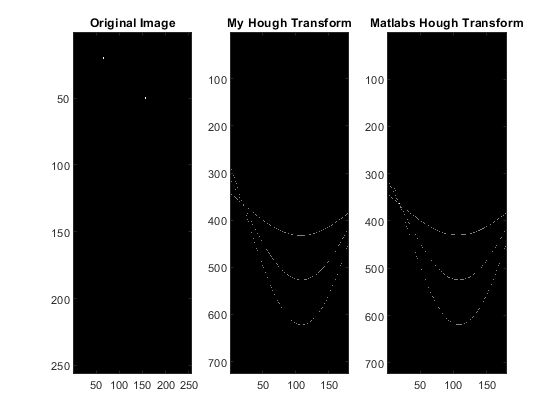

subplot(1,3,3); imagesc(matlab_hough); title('Matlabs Hough Transform');  h = gca; h.Visible = 'On';
colormap gray

**Are they roughly the same? If not, why?**

On visual inspection, they are very similar, as are the dimensions. To get a more quantitative feel for how these images are different, we can subtract the two images to see exactly where the differences lie. 

size(my_hough)

ans =    726   180


size(matlab_hough)

ans =    723   180


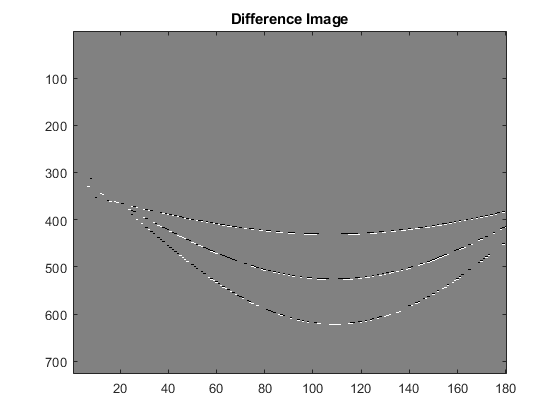


matlab_hough(724:726,:) = zeros(3,180); % Add 3 more rows to match size of my hough transform
figure; imagesc(my_hough - matlab_hough); title('Difference Image'); h = gca; h.Visible = 'On'; colormap gray

Based on the difference images, it appears that the sinusoidal trajectory off the three points are shifted by a small amount. This shift is likely due to a rounding issue.

**(c) Load the leg_after.jpg image into Matlab. You can download it from **`https://danielpimentel.github.io/teaching.html`**. Transform it to grayscale using your code from Homework 1. Show your code, and use **`subplot`** to display **

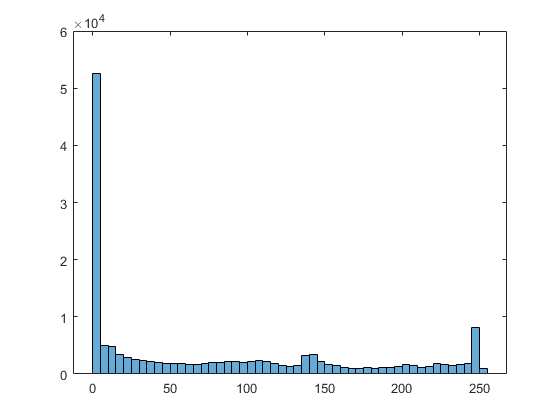

leg_after = imread('leg_after.jpg');
leg_after = rgb2gray(leg_after);
figure; histogram(leg_after);

- **(i) the original image        **

figure; subplot(1,3,1); imagesc(leg_after); title('Original Image');

- **(ii) its Hough transform produced by your code**

% tic; my_hough = hough_transform(leg_after); toc
tic; my_hough = hough_transform_fast(leg_after); toc

Elapsed time is 28.350639 seconds.


subplot(1,3,2); imagesc(my_hough); title('My Hough Transform'); h = gca; h.Visible = 'On';

- **(iii) its Hough transform produced by Matlab's **`hough`** function. **

tic; matlab_hough = hough(leg_after); toc

Elapsed time is 0.066178 seconds.


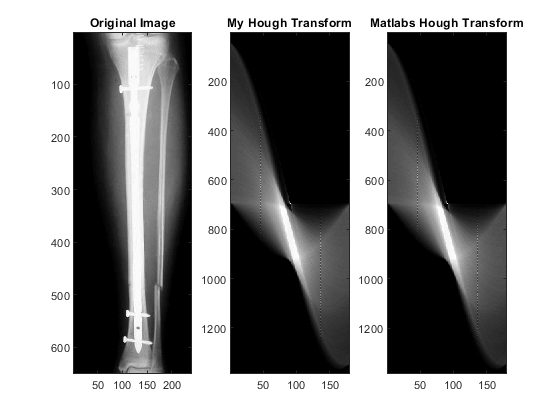

subplot(1,3,3); imagesc(matlab_hough); title('Matlabs Hough Transform');  h = gca; h.Visible = 'On';
colormap gray

**(d) Using the histogram above as guideline, find a threshold that segments the metal rod. Show your code, and use subplot to display **

- **(i) the original image**

figure; subplot(1,2,1); imagesc(leg_after); title('Original Image');

- **(ii) the thresholded (binary) image**

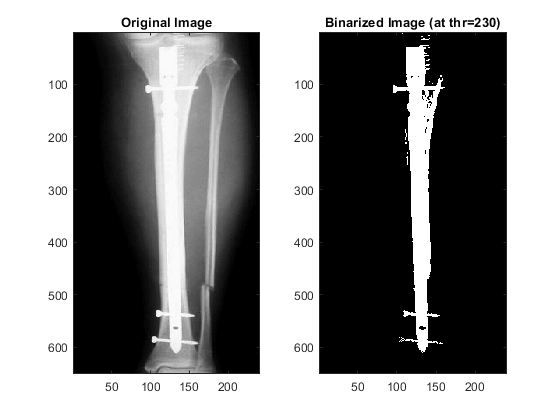

leg_mask = leg_after>230;
subplot(1,2,2); imagesc(leg_mask); title('Binarized Image (at thr=230)');
colormap gray

- **(iii) its Hough transform produced by your code**

% tic; my_hough = hough_transform(leg_after); toc
tic; my_hough = hough_transform_fast(leg_mask); toc

Elapsed time is 3.001165 seconds.


figure; subplot(1,2,1); imagesc(my_hough); title('My Hough Transform'); h = gca; h.Visible = 'On';

- **(iv) its Hough transform produced by Matlab's **`hough`** function.**

tic; matlab_hough = hough(leg_mask); toc

Elapsed time is 0.011713 seconds.


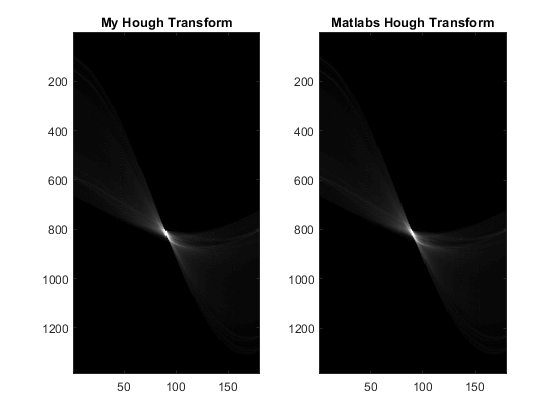

subplot(1,2,2); imagesc(matlab_hough); title('Matlabs Hough Transform');  h = gca; h.Visible = 'On';
colormap gray

**(e) Based on the Hough transform, what are the (approximate) values of **$\theta$** and *****r*****  that describe the line of the rod? Do these values make sense?**

We can see that the highest values lie approximately between theta values of 85-95 degrees and radius values from 790-840. These values makes sense, because the large metal rod is located approximately between the these indices on the image and it is running parallel to the image sides (90 degrees). The reason there is a spread in angle and in radius values is because the rod is not a single line, but rather a thick rod (composed of many lines). This implies multiple radius values *and *multiple angles that can run through the rod (say from top left to bottom right). 

**(f) Repeat the same procedure for the image **`leg_before.jpg`**, also available in the same website. What are your observations/conclusions? Display whatever images you think necessary to make your points.**

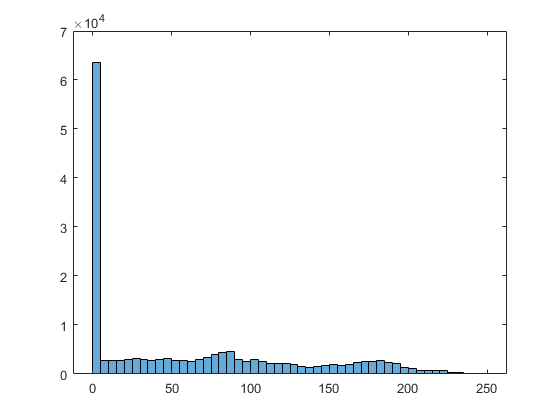

leg_before = imread('leg_before.jpg');
leg_before = rgb2gray(leg_before);
figure; histogram(leg_before);

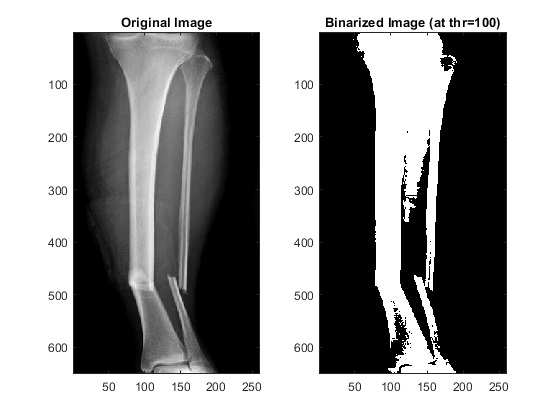


figure; subplot(1,2,1); imagesc(leg_before); title('Original Image');

leg_mask = leg_before>100;
subplot(1,2,2); imagesc(leg_mask); title('Binarized Image (at thr=100)');
colormap gray


% tic; my_hough = hough_transform(leg_after); toc
tic; my_hough = hough_transform_fast(leg_mask); toc

Elapsed time is 10.382137 seconds.


figure; subplot(1,2,1); imagesc(my_hough); title('My Hough Transform'); h = gca; h.Visible = 'On';

tic; matlab_hough = hough(leg_mask); toc

Elapsed time is 0.020617 seconds.


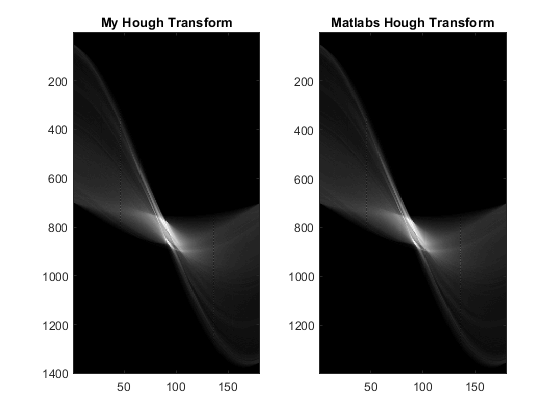

subplot(1,2,2); imagesc(matlab_hough); title('Matlabs Hough Transform');  h = gca; h.Visible = 'On';
colormap gray

There are several differences between the before and after Hough transformed leg images. Firstly, there is not a localized bright area as there was in the previous example. This is because we are now looking at the tibia and fibula, which are much larger than the rod, creating a more diffuse "bright" point. Secondly, we see that there are several other bright areas. These areas are likely due to the inferior part of the tibia and fibula, which are angled slightly from the superior tibia and fibula due to the fracture. Lastly, there are more points in this Hough transformed image due to the fact that we used a lower threshold (more active points in the binarized image) compared to the last image.

### Custom Functions

function accumulate = hough_transform(I)
    dim1 = size(I,1);
    dim2 = size(I,2);
    
    if ~isa(I,'logical')
        I = I>0;
    end
    
    thetas = deg2rad(-90:89); % create array vector of all possible thetas
    D = ceil(sqrt(dim1^2 + dim2^2)); % find max value of r
    [x,y] = find(I); % find the points of interest
    accumulate = zeros(2*D,180); % initialize accumulation map
    for t = 1:length(thetas) % for every angle
        for i = 1:length(x) % for each active pixel
            r = round( x(i)*sin(thetas(t)) + y(i)*cos(thetas(t)) ) + D; % find the radius at each point
            accumulate(r,t) = accumulate(r,t)+1; % add to accumulation map
        end
    end 
end

function accumulate = hough_transform_fast(I)
    if ~isa(I,'logical')
        I = I>0;
    end
    
    [x,y] = find(I); % find the active points
    x = repmat(x,1,180); % repeat this vector 180 points (size = n x 180)
    y = repmat(y,1,180); % repeat this vector 180 points. (size = n x 180)
    thetas = repmat(deg2rad(-90:89),size(x,1),1); % create vector of all thetas and repeat by # of active points (size = n x 180)
    accumulate = zeros(2*ceil(sqrt(size(I,1)^2 + size(I,2)^2)),180); % initialize accumulation map (size = 2*D x 180)
    r = round( x.*sin(thetas) + y.*cos(thetas) ) + ceil(sqrt(size(I,1)^2 + size(I,2)^2));
    uniq = unique(r); % get unique r values
    for i=1:length(uniq)
        accumulate(uniq(i),:) = sum(r==uniq(i)); % count how many unique r's for all thetas and place in accumulate
    end
end